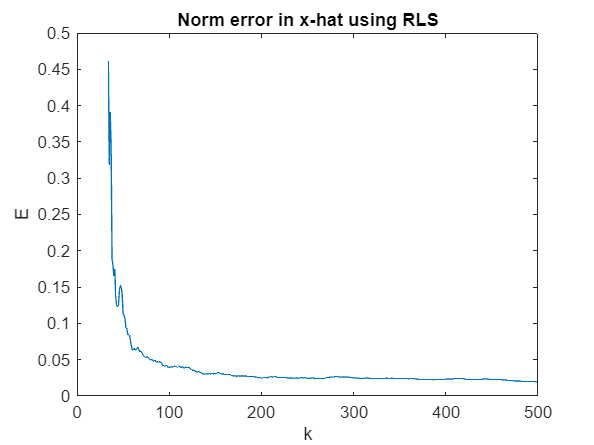

%HW 7 Q4c
tic
close all
clear 
clc
load("DataHW07_Prob4.mat")
S = eye(3);
temp = cell2mat(C(1));
temp_1 = size(temp);
n = ceil(temp_1(2)/temp_1(1));


for i = 1:n
    if (i == 1)
        Qk = cell2mat(C(1))'*eye(3)*cell2mat(C(1));
        Tk = cell2mat(C(1))'*eye(3)*cell2mat(y(1));
    else
        Qk = Qk + cell2mat(C(i))'*eye(3)*cell2mat(C(i));
        Tk = Tk + cell2mat(C(i))'*eye(3)*cell2mat(y(i));
    end
end
xk = inv(Qk)*Tk;
for k = n:N-1
    Q1 = Qk + cell2mat(C(k+1))'*eye(3)*cell2mat(C(k+1));
    Qk = Q1;
    K_k_1 = inv(Q1) * cell2mat(C(k+1))' * eye(3);
    temp = K_k_1*(cell2mat(y(k+1)) - (cell2mat(C(k+1))*xk));
    x_k_k = xk + temp(:,1);
    xk = x_k_k;

    Ek_temp = x_k_k - cell2mat(x_actual(k));
    Ek_temp1 = Ek_temp.^2;
    if (k == n)
    Ek = sum(Ek_temp1)^0.5;
    else
    Ek = [Ek;(sum(Ek_temp1))^0.5];
    end
end
plot(n:N-1,Ek)
title('Norm error in x-hat using RLS')
xlabel('k')
ylabel('E')


toc

Elapsed time is 2.130559 seconds.
